%% Bode Method
Mp = 0.1;
ts = 0.15;
d = log(1/Mp) / sqrt(pi^2 + log(1/Mp)^2);   %   damping factor
d

d = 0.5912

w_gc = 3/(d*ts);    %   gain crossover freq [rad/s]      
w_gc

w_gc = 33.8321

ph_m = 180/pi * atan(2*d/sqrt(sqrt(1+4*d^4)-2*d^2));
ph_m

ph_m = 58.5931

[kp, ki, kd] = BodMet(w_gc,ph_m,simp_model);
kp

kp = 8.3738

ki

ki = 111.2674

kd

kd = 0.1575

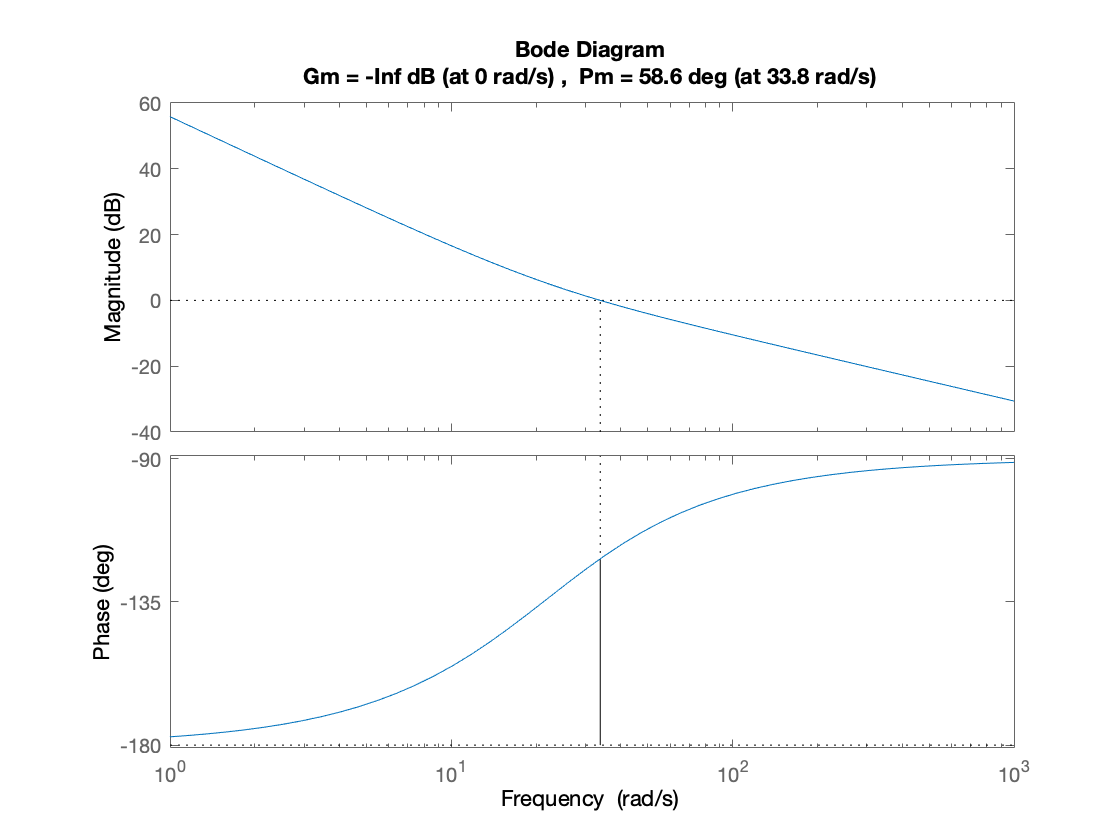

s = tf('s');
bod_met.controller = kp + ki/s + kd*s/(0.000*s+1);
margin(bod_met.controller*simp_model.P)

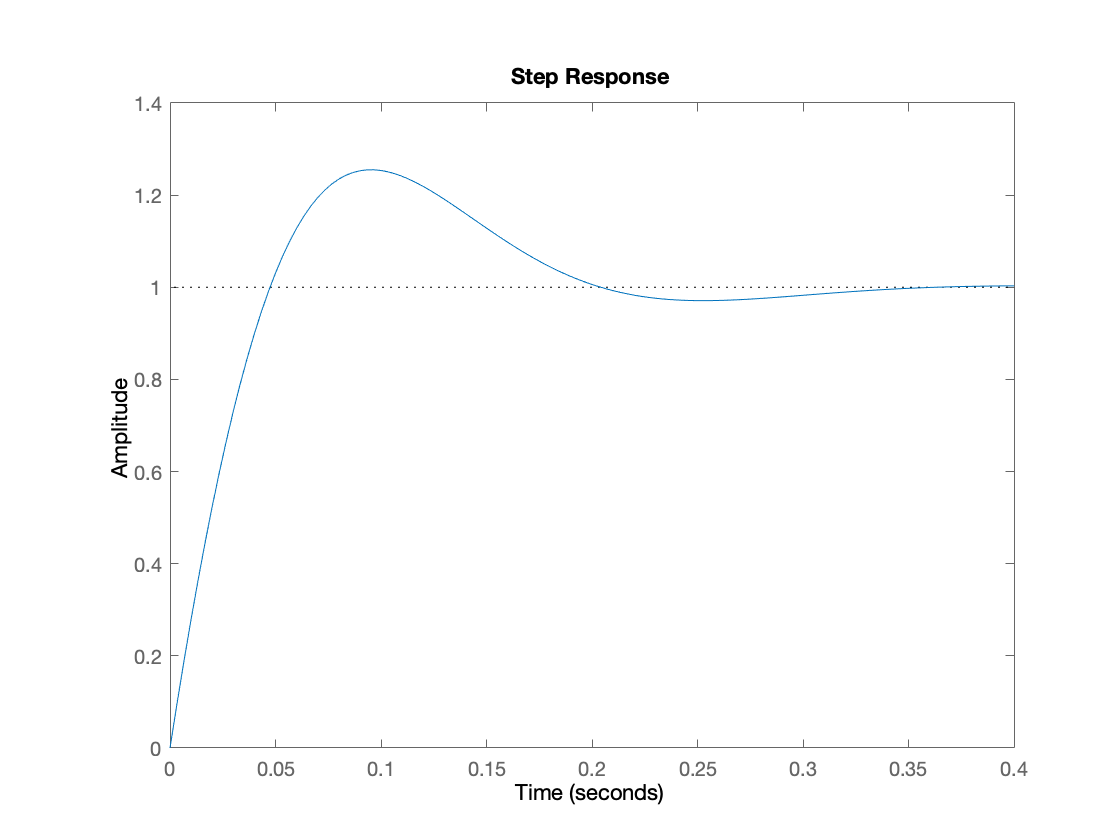

bod_met.W = feedback(bod_met.controller*simp_model.P,1);
charac.tr = stepinfo(bod_met.W).RiseTime;
charac.ts = stepinfo(bod_met.W).SettlingTime;
charac.mp = stepinfo(bod_met.W).Overshoot;

step(bod_met.W)

charac

charac = struct with fields:
    tr: 0.0366
    ts: 0.2927
    mp: 25.5024



kp

kp = 8.3738

ki

ki = 111.2674

kd

kd = 0.1575

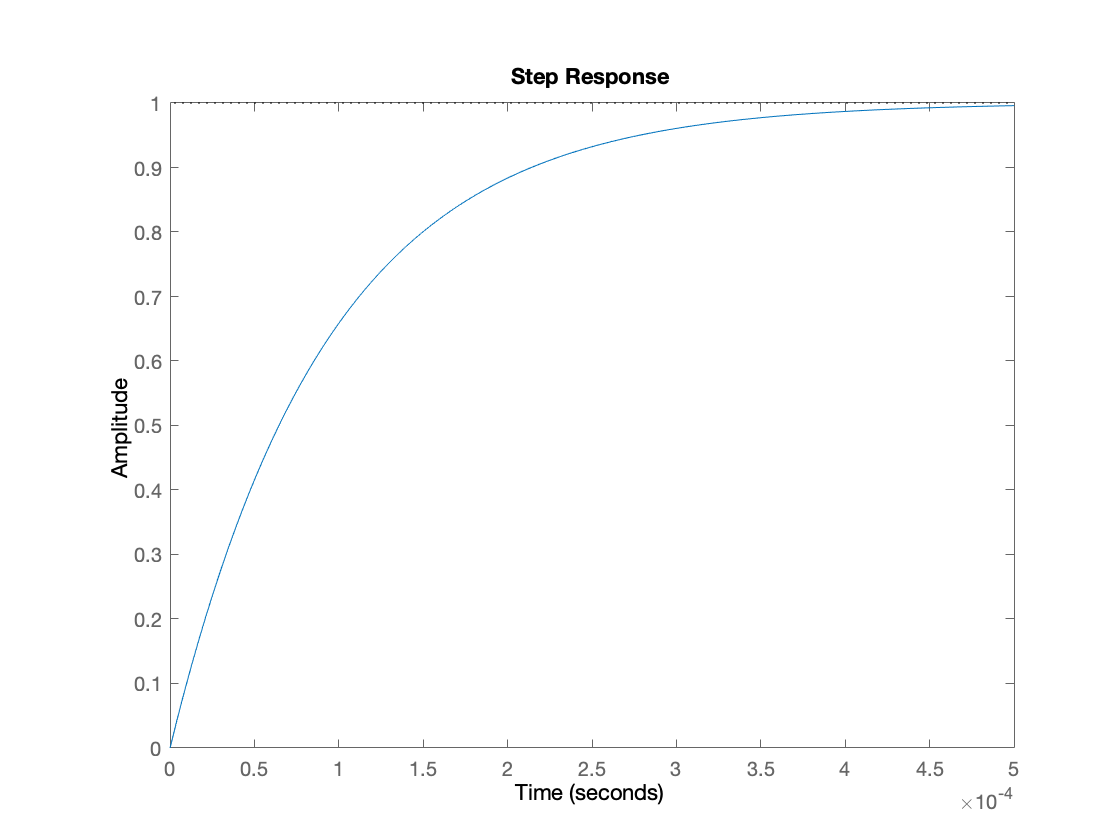


%% best Kp, Ki, Kd
deltaKp = 4; 
deltaKi = 20; 
deltaKd = 1; 
K_p = 40:deltaKp:60;
K_i = 80:deltaKi:180;
K_d = 1:deltaKd:10;
kp_best = kp;
ki_best = ki;
kd_best = kd;
tss = charac.ts;
trr = charac.tr;
mpp = charac.mp;
for KP=K_p
    for KI=K_i
        for KD=K_d
           s = tf('s');
           C = KP+KI/s+KD*s/(0*s+1);
           W = feedback(C*simp_model.P*rad2deg,1);
           if (stepinfo(W).SettlingTime < tss && stepinfo(W).Overshoot < mpp)
                 tss = stepinfo(W).SettlingTime;
                 mpp = stepinfo(W).Overshoot;
                 kp_best = KP;
                 ki_best = KI;
                 kd_best = KD;
           end
        end
    end
end
bod_met.best_controller = kp_best+ki_best/s+kd_best*s/(0*s+1);
bod_met.best_W = feedback(bod_met.best_controller * simp_model.P*rad2deg,1);
figure(2);
step(bod_met.best_W)

kp

kp = 7.5244

ki

ki = 94.0379

kd

kd = 0.1505

kp_best = 60

kp_best = 60

ki_best = 100

ki_best = 100

kd_best = 1

kd_best = 1

%% Function definition

function [kp, ki, kd] = BodMet(w_gc,ph_m,simp_model)
%d = log(1/Mp) / sqrt(pi^2 + log(1/Mp)^2);   %   damping factor
%d
%w_gc = 3/(d*ts);    %   gain crossover freq [rad/s]      
%w_gc
%ph_m = 180/pi * atan(2*d/sqrt(sqrt(1+4*d^4)-2*d^2));
%ph_m
[mag_wgc, phm_wgc] = bode(simp_model.P,w_gc); % gain,phase of P(iw_gc)
deltaK = 1/mag_wgc; % DeltaK
deltaPhi = -180 + ph_m - phm_wgc; % DeltaPhi
kp = deltaK * cosd(deltaPhi); % K_p
T_d = (tand(deltaPhi) + sqrt(tand(deltaPhi)^2 + 1))/(2*w_gc); % T_d
T_i = 4*T_d; % T_i
ki = kp/T_i; % K_i
kd = kp*T_d; % K_d
end